# 小さな例でのMarkovレーティング

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

係数行列を定義する

X=[1 -1 0;
    1 -1 0;
    0 1 -1;
    0 1 -1;
    -1 0 1];
y=[20;5;5;-5;-10];

勝敗数およびそれを変換した遷移行列を計算する

V=zeros(size(X,2));
S=zeros(size(X,2));
for n1=1:size(X,1)
    taNum=find(X(n1,:)==1);
    tbNum=find(X(n1,:)==-1);
    if y(n1)>0
        V(taNum,tbNum)=V(taNum,tbNum)+1;
    else
        V(tbNum,taNum)=V(tbNum,taNum)+1;
    end
end
V

V =      0     2     1
     0     0     1
     0     1     0


for n2=1:size(V,2)
    if sum(V(:,n2))>0
        S(:,n2)=V(:,n2)/sum(V(:,n2));
    end
end
S

S =          0    0.6667    0.5000
         0         0    0.5000
         0    0.3333         0


初期ベクトルを設定したMarkov連鎖を計算してみる．

rng(1); %コメントアウトすると書籍と同じ図が得られる
r=rand(size(S,2),1);r=r/sum(r);
tmpR=r;
for k=1:10
    tmpR=S*tmpR;
    r=[r tmpR];
end
tmpR

tmpR = 1.0e-04 *

    0.8147
    0.8144
    0.0001


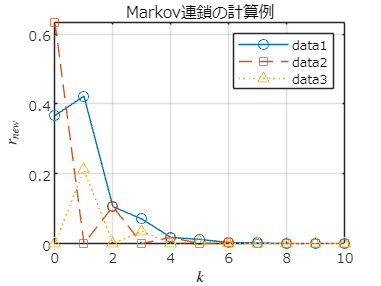

figure;
plot(0:10, r');
ax=gca;
mylinestyles = ["-o"; "--s"; ":^"];
ax.LineStyleOrder = mylinestyles;
ax.LineStyleCyclingMethod = "withcolor";
set(gca,'fontname','メイリオ');grid on;
xlabel('$k$','Interpreter','latex');ylabel('$r_{new}$','Interpreter','latex');
legend;
title('Markov連鎖の計算例');
exportgraphics(gcf,"fig_smallExample_Markov.pdf");

有向グラフとして図示する

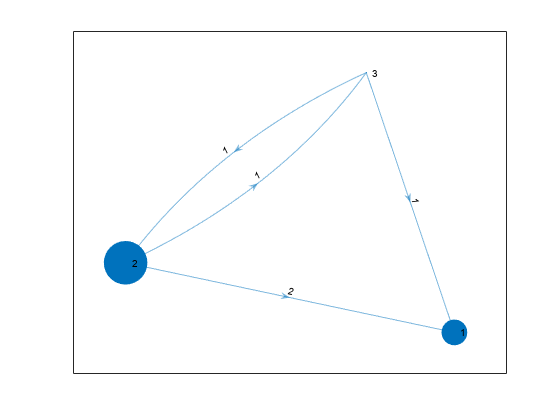

G=digraph(V');
figure
gObj=plot(G,"EdgeLabel",G.Edges.Weight);

for n1=1:size(r,2)
    gObj.MarkerSize=r(:,n1)*50;
    drawnow
end

Markovレーティングを算出する

b=0.85;
r=inv(eye(size(S))-b*S)*(1-b)*ones(size(X,2),1)/size(X,2)

r =     0.1269
    0.0810
    0.0730
